%This script serves for the OECT capacitance modelling%
%Start Date: 2022/05/30
%Last Edit Date: 2022/06/02
%Latest Update History: Successfully present the meshwork plotting

%Initialization%
clc;clear all; close all;

%%Simplest Model%%
%Variable definition%
f = (10^-1):0.1:10^6;
w = 2*pi*f; %Angular frequency
Cch = 100e-9; Cg = Cch; Cb = 10; %Capacitance of channel side/gate side/bilayer
Ri =1000; %Internal Resistance

%Equation Modelling%
Uch_Y = (1./(j*w*Cch))./(1./(j*w*Cg)+1./(j*w*Cch)+Ri); %With capacitive limitation
Uch_N = 1./(j*w*Cch)./(1./(j*w*Cch)+Ri); %Without capacitive limitation
f1 = 1000; w1 = 2*pi*f1;
Cg_R = [10^-3:0.001:10^3]*Cch;
Uch_R = (1./(j*w1*Cch))./(1./(j*w1*Cg_R)+1./(j*w1*Cch)+Ri);


%Plotting%
figure
semilogx(f,Uch_Y,'black','LineStyle','--');title('Simplest Model');xlabel('f (Hz)');ylabel('Uch');

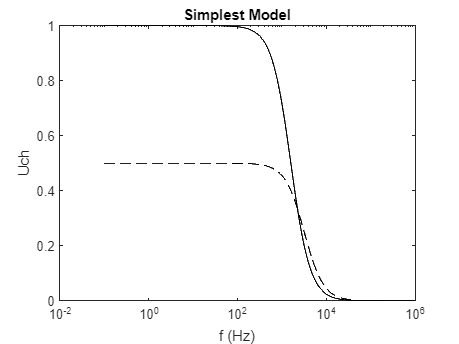

hold on
semilogx(f,Uch_N,'black');figure

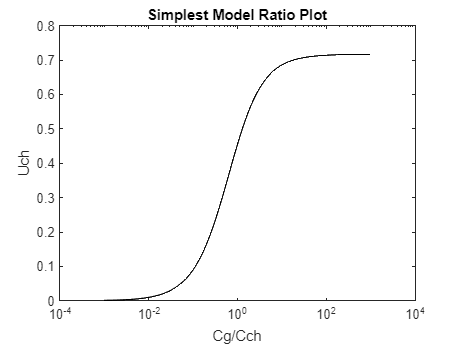

semilogx([10^-3:0.001:10^3],Uch_R,'black');title('Simplest Model Ratio Plot');xlabel('Cg/Cch');ylabel('Uch');

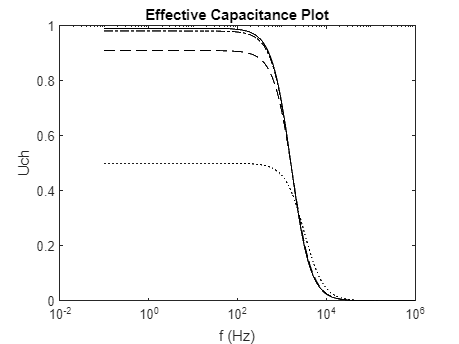

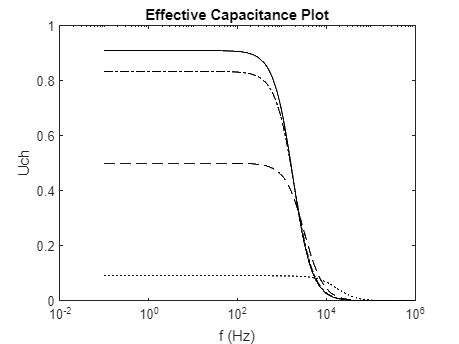

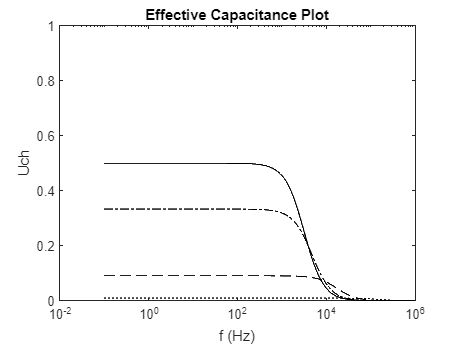



%Effective Gate Capacitance%
Cg = [100*Cch, 10*Cch, Cch];
for loop = 1:length(Cg)
    Uch_e = (1./(j*w*Cch))./(1./(j*w*Cg(loop))+1./(j*w*Cch)+Ri); %With different effective capacitance
    figure
    semilogx(f,Uch_e,'black','LineStyle','-');title('Effective Capacitance Plot');xlabel('f (Hz)');ylabel('Uch');
    hold on
    %Cgs = [0.5*Cg(loop), 0.1*Cg(loop), 0.01*Cg(loop)];
    Uch_e = (1./(j*w*Cch))./(1./(j*w*0.5*Cg(loop))+1./(j*w*Cch)+Ri); %With different effective capacitance
    semilogx(f,Uch_e,'black','LineStyle','-.');
    hold on
    Uch_e = (1./(j*w*Cch))./(1./(j*w*0.1*Cg(loop))+1./(j*w*Cch)+Ri); %With different effective capacitance
    semilogx(f,Uch_e,'black','LineStyle','--'); ylim([0 1]);
    hold on    
    Uch_e = (1./(j*w*Cch))./(1./(j*w*0.01*Cg(loop))+1./(j*w*Cch)+Ri); %With different effective capacitance
    semilogx(f,Uch_e,'black','LineStyle',':'); ylim([0 1])
    
end

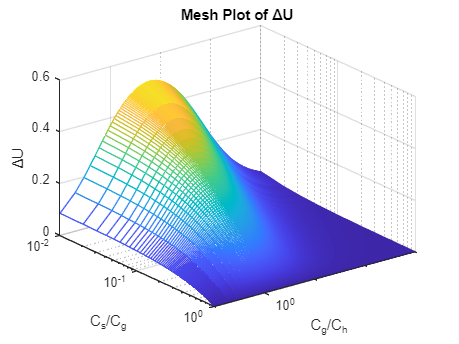



%Delta_U Meshwork Plotting%
%Variable definition%
f_Mesh = 10; %Can be changed to any other frequency
w_Mesh = 2*pi*f_Mesh; %Angular frequency
Cch = 100e-9; %Capacitance of channel side
Ri =1000; %Internal Resistance
R_g2Ch = 10^-1 :0.1: 10^3;
R_gs2g = 1:-(10^-2):10^-2;
dU = []; %Create an empty array to store the delta U
for i = 1: length(R_g2Ch)
    Cg = Cch * R_g2Ch(i); % Put it here to reduce the computation burden
    for j = 1:length(R_gs2g)
        Cgs = Cg * R_gs2g(j);
        Uch_reference = (1./(j*w_Mesh*Cch))./(1./(j*w_Mesh*Cg)+1./(j*w_Mesh*Cch)+Ri);
        Uch_gs = (1./(j*w_Mesh*Cch))./(1./(j*w_Mesh*Cgs)+1./(j*w_Mesh*Cch)+Ri);
        dU(j) = Uch_reference - Uch_gs;
    end
    RdU(i,:)=dU;
    
end
RdU = RdU.';
figure
mesh(R_g2Ch,R_gs2g,RdU);set(gca,'xscale','log');set(gca,'yscale','log');set(gca,'YDir','reverse');
xlabel("C_g/C_c_h");ylabel("C_g_,_s/C_g");zlabel("ΔU");title("Mesh Plot of ΔU")



%%Bilyaer Presented Model%%
%Variable definition%
%Rb = 10; % Bilayer Resistance in ohmcm^2

%Equation Modelling%
%Uch_b = (1./j*w*Cch)./((1./j*w*Cg)+(1./(j*w*Cb + 1/Rb)+Ri+(1./(j*w*Cch))));
